# **Week 5 : Examining BER vs Link Length in the Presence of CD**

The code below examines the variation of the bit error rate (BER) with the variation of the totla fibre length in the presence of chromatic dispersion (CD)

## **Transmitter**

The model of the transmitter consists of the following elements:

- A symbol generator which modulates source bits using BPSK and QPSK.

- An IQ modulator which modulates the output of a laser according to an electrical signal.

### Modulation

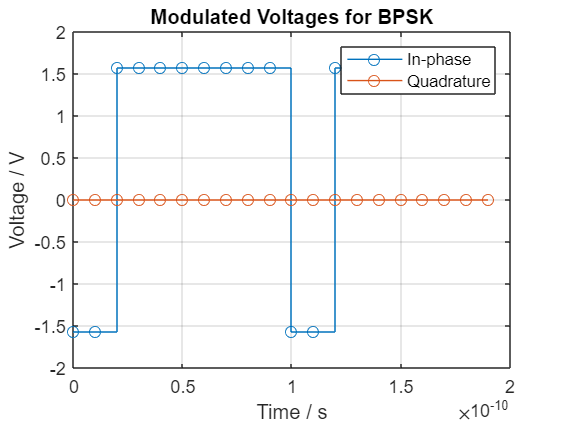

clear all; clearvars;

% Parameters
NSymb = 500000; % No. of symbols 
SpS = 2; % Samples per symbol
Rs = 50e9; % Symbol rate in symbols/sec
maxLength = 80; % Maximum fibre length in kilometres
deltaLength = 4; % Difference between successive sampled lengths of fibre in kilometres
lengthSamples = 0:deltaLength:maxLength; % sampled link lengths in kilometres
T = 1/(SpS*Rs); % Sampling period in s
t= [0:1:NSymb*SpS - 1]*T; % Time vector for plotting time-series data

voltageLevels = [-pi/2, pi/2]'; % Discrete voltage levels for BPSK and QPSK
DCOffset = 0; % DC offset of modulated current in V

% -------------------------------------------------------------------------------

% FOR BPSK:
% Generating random bit sequence(s)
sourceBitsBPSK = randi([0 1], NSymb, length(lengthSamples)); % Matrix of source bits for BPSK
sourceSymbolsBPSK = pskmod(sourceBitsBPSK, 2); % Maps source bit vector to symbol vector

% Modulating voltage with generated symbols
vI_BPSK = ones(size(sourceSymbolsBPSK)); vQ_BPSK = zeros(size(sourceSymbolsBPSK));

vI_BPSK(real(sourceSymbolsBPSK)>0) = voltageLevels(2); % Maps 1 -> pi/2
vI_BPSK(real(sourceSymbolsBPSK)<0) = voltageLevels(1); % Maps -1 -pi/2

vI_BPSK_upsampled = repelem(vI_BPSK, SpS, 1); % Upsampling according to SpS
vQ_BPSK_upsampled = repelem(vQ_BPSK, SpS, 1); % Upsampling according to SpS

% Visualising in-phase voltage
stairs(t(1:10*SpS), vI_BPSK_upsampled(1:10*SpS,1), "o-");
hold on
stairs(t(1:10*SpS), vQ_BPSK_upsampled(1:10*SpS,1), "o-");
title("Modulated Voltages for BPSK")
xlabel("Time / s")
ylabel("Voltage / V")
legend("In-phase", "Quadrature")
grid on
hold off

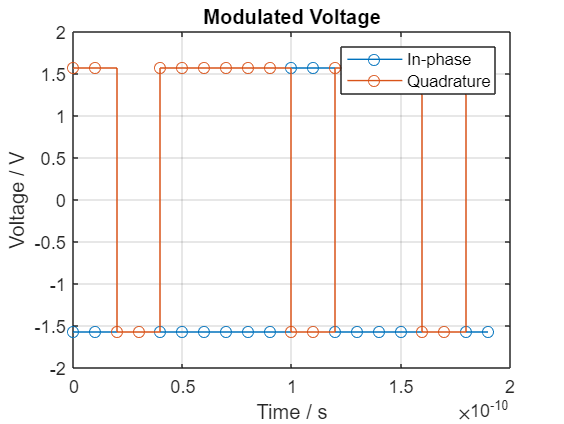


% -------------------------------------------------------------------------------

% FOR QPSK:
% Generating random bit sequence(s)
sourceBitsQPSK = randi([0 1], NSymb*2, length(lengthSamples)); % Matrix of source bits for QPSK
sourceIntsQPSK = bit2int(sourceBitsQPSK, 2); % Vector of source bits converted to ints
sourceSymbolsQPSK = pskmod(sourceIntsQPSK, 4, pi/4); % Maps source bit vector to symbol vector

% Modulating voltage with generated symbols
vI_QPSK = ones(size(sourceSymbolsQPSK)); vQ_QPSK = zeros(size(sourceSymbolsQPSK));

vI_QPSK(real(sourceSymbolsQPSK)>0) = voltageLevels(2); % Maps 1 -> pi/2
vI_QPSK(real(sourceSymbolsQPSK)<0) = voltageLevels(1); % Maps -1 -pi/2
vQ_QPSK(imag(sourceSymbolsQPSK)>0) = voltageLevels(2); % Maps 1 -> pi/2
vQ_QPSK(imag(sourceSymbolsQPSK)<0) = voltageLevels(1); % Maps -1 -pi/2

vI_QPSK_upsampled = repelem(vI_QPSK, SpS, 1); % Upsampling according to SpS
vQ_QPSK_upsampled = repelem(vQ_QPSK, SpS, 1); % Upsampling according to SpS

% Visualising in-phase and quadrature voltage
stairs(t(1:10*SpS), vI_QPSK_upsampled(1:10*SpS,1), "o-");
hold on
stairs(t(1:10*SpS), vQ_QPSK_upsampled(1:10*SpS,1), "o-");
title("Modulated Voltage")
xlabel("Time / s")
ylabel("Voltage / V")
legend("In-phase", "Quadrature")
grid on
hold off

### IQ Modulation

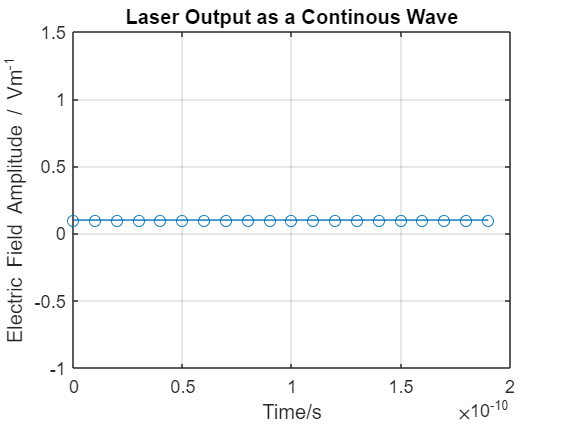

% Initialising laser parameters
lineWidth = 0;
laserPw_dBm = 10;
laserPw_Lin = 1e-3*10^(laserPw_dBm/10);

% Generating output from laser modelled as a contniuous-wave source
laserE = Laser(laserPw_dBm, lineWidth, SpS, Rs, NSymb, 1); % Laser output to be used with unshaped signals

% Visualising output from laser
plot(t(1:20), real(laserE(1:20)), "o-");
title("Laser Output as a Continous Wave");
xlabel("Time/s")
ylabel("Electric Field Amplitude / Vm^{-1}");
grid on

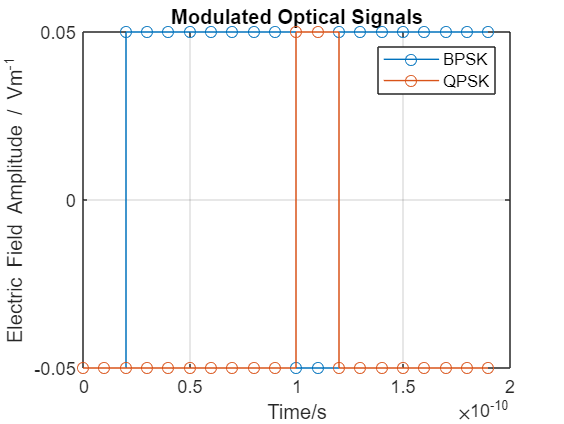


% Modulating optical signal using IQM
Vpi = pi/2; % Voltge required to change phase of E-field by pi

modOpticSigBPSK = IQModulatorModified(vI_BPSK_upsampled, vQ_BPSK_upsampled, laserE, Vpi);
modOpticSigQPSK = IQModulatorModified(vI_QPSK_upsampled, vQ_QPSK_upsampled, laserE, Vpi);

% Visualising modulated optical signals
stairs(t(1:10*SpS), real(modOpticSigBPSK(1:10*SpS,1)), "o-");
hold on
stairs(t(1:10*SpS), real(modOpticSigQPSK(1:10*SpS,1)), "o-");
title("Modulated Optical Signals")
xlabel("Time/s")
ylabel("Electric Field Amplitude / Vm^{-1}")
legend("BPSK", "QPSK")
grid on
hold off

## Optical Channel

### Adding CD

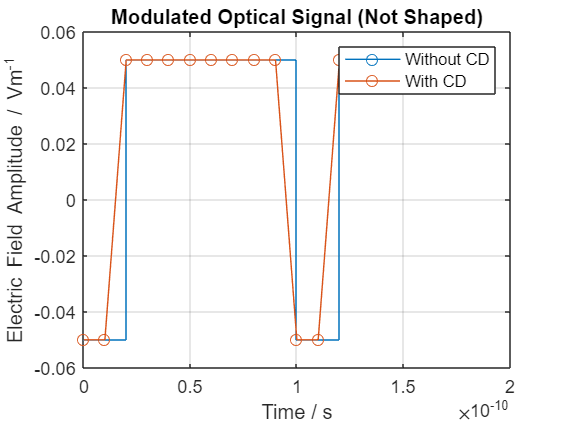

D = 17; % Group velocity dispersion in ps/nm/km
CLambda = 1550e-9; % Central wavelength of optical carrier in m

for i=1:length(lengthSamples)
    modOpticSigBPSK_CD(:,i) = CDInsertion(modOpticSigBPSK(:,i), SpS, Rs, D, CLambda, lengthSamples(i)*10^3, 1);
    modOpticSigQPSK_CD(:,i) = CDInsertion(modOpticSigQPSK(:,i), SpS, Rs, D, CLambda, lengthSamples(i)*10^3, 1);
end

% Visualising optical signal before and after CD insertion:
% Without Pulse Shaping
stairs(t(1:10*SpS), real(modOpticSigBPSK(1:10*SpS,1)), "-o"); 
hold on
plot(t(1:10*SpS), real(modOpticSigBPSK_CD(1:10*SpS,1)), "-o");
xlabel("Time / s"); 
ylabel("Electric Field Amplitude / Vm^{-1}")
title("Modulated Optical Signal (Not Shaped)")
legend("Without CD", "With CD")
grid on
hold off

## Receiver

### Optical Front-End

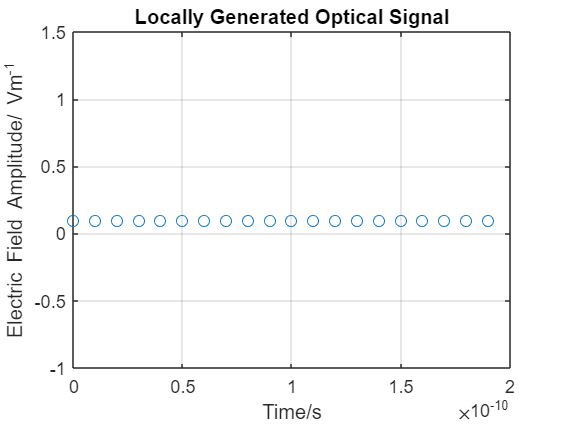

% Generating Local optical signal for coherent detection
Elo = laserE; % Identical to initial laser source

% Visualising locally generated optical signal
plot(t(1:20), real(Elo(1:20,1)), "o");
title("Locally Generated Optical Signal");
xlabel("Time/s")
ylabel("Electric Field Amplitude/ Vm^{-1}")
grid on


% Generating output from optical front-end
eta_ph = 0.3; % Responsivity of photodetectors

count = 1;
for i=1:size(modOpticSigBPSK_CD,2)  % Output from Optical Front-End
    % Signals with CD
    OpticFEOutBPSK(:,count:count+1) = OpticalFrontEnd(modOpticSigBPSK_CD(:,i), Elo, eta_ph, 1);
    OpticFEOutQPSK(:,count:count+1) = OpticalFrontEnd(modOpticSigQPSK_CD(:,i), Elo, eta_ph, 1);

    % Test signals with no added CD
    testFEOutBPSK(:,count:count+1) = OpticalFrontEnd(modOpticSigBPSK(:,i), Elo, eta_ph, 1);
    testFEOutQPSK(:,count:count+1) = OpticalFrontEnd(modOpticSigQPSK(:,i), Elo, eta_ph, 1);

    count = count+2;
end

% TIA amplification and sampling using ADC
TIA_Gain = 1; % TIA amplification factor
Fs = SpS; % Sampling frequency of ADC

% Amplification and separation of in-phase and quadrature components
% BPSK
OpticFEOutBPSK_I = TIA_Gain*OpticFEOutBPSK(:, 1:2:end); OpticFEOutBPSK_Q = TIA_Gain*OpticFEOutBPSK(:, 2:2:end); % With CD
testFEOutBPSK_I = TIA_Gain*testFEOutBPSK(:, 1:2:end); testFEOutBPSK_Q = TIA_Gain*testFEOutBPSK(:, 2:2:end); % Without CD
% QPSK
OpticFEOutQPSK_I = TIA_Gain*OpticFEOutQPSK(:, 1:2:end); OpticFEOutQPSK_Q = TIA_Gain*OpticFEOutQPSK(:, 2:2:end); % With CD
testFEOutQPSK_I = TIA_Gain*testFEOutQPSK(:, 1:2:end); testFEOutQPSK_Q = TIA_Gain*testFEOutQPSK(:, 2:2:end); % Without CD



## DSP

### Scaling and Downsampling

% Scaling factor between output of IQM and output of optical front-end
laserEMag = sqrt(laserPw_Lin);
scaleFactor = TIA_Gain*eta_ph*laserEMag*laserEMag/2;

% Cancelling the scaling factor and downsampling:
% BPSK
voltageI_BPSK = OpticFEOutBPSK_I(1:SpS:end, :)/scaleFactor; voltageQ_BPSK = OpticFEOutBPSK_Q(1:SpS:end, :)/scaleFactor; % With CD
testVI_BPSK = testFEOutBPSK_I(1:SpS:end, :)/scaleFactor; testVQ_BPSK = testFEOutBPSK_Q(1:SpS:end, :)/scaleFactor; % Without CD
% QPSK
voltageI_QPSK = OpticFEOutQPSK_I(1:SpS:end, :)/scaleFactor; voltageQ_QPSK = OpticFEOutQPSK_Q(1:SpS:end, :)/scaleFactor; % With CD
testVI_QPSK = testFEOutQPSK_I(1:SpS:end, :)/scaleFactor; testVQ_QPSK = testFEOutQPSK_Q(1:SpS:end, :)/scaleFactor; % Without CD


### Decoding and Decision

% Decoding recieved symbols

% BPSK
% With CD
decodedSymbolsBPSK = ones(size(voltageI_BPSK)); 
decodedSymbolsBPSK(voltageI_BPSK > 0) = 1; decodedSymbolsBPSK(voltageI_BPSK <= 0) = -1;
decodedIntsBPSK = pskdemod(decodedSymbolsBPSK, 2);
decodedBitsBPSK = int2bit(decodedIntsBPSK, 1);

% Test voltages
testSymbolsBPSK = ones(size(testVI_BPSK)); 
testSymbolsBPSK(testVI_BPSK > 0) = 1; testSymbolsBPSK(testVI_BPSK <= 0) = -1;
testIntsBPSK = pskdemod(testSymbolsBPSK, 2);
testBitsBPSK = int2bit(testIntsBPSK, 1);
biterr(testBitsBPSK, sourceBitsBPSK)

ans = 0


% --------------------------------------------------------------------------------------------

% QPSK
% With CD
decodedSymbolsQPSK = voltageI_QPSK + 1i*voltageQ_QPSK;
decodedIntsQPSK = pskdemod(decodedSymbolsQPSK, 4, pi/4);
decodedBitsQPSK = int2bit(decodedIntsQPSK, 2);

testSymbolsQPSK = testVI_QPSK + 1i*testVQ_QPSK;
testIntsQPSK = pskdemod(testSymbolsQPSK, 4, pi/4);
testBitsQPSK = int2bit(testIntsQPSK, 2);
biterr(testBitsQPSK, sourceBitsQPSK)

ans = 0

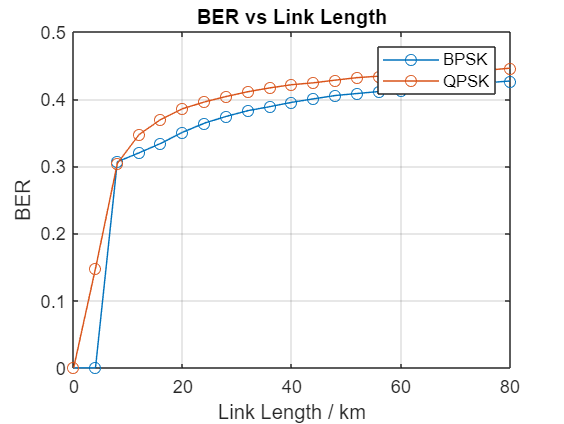


for i=1:length(lengthSamples)
    [~, BER_BPSK(i,1)] = biterr(decodedBitsBPSK(:,i), sourceBitsBPSK(:,i));
    [~, BER_QPSK(i,1)] = biterr(decodedBitsQPSK(:,i), sourceBitsQPSK(:,i));
end

% Visualising variation of BER with link length

plot(lengthSamples, BER_BPSK, "-o");
hold on
plot(lengthSamples, BER_QPSK, "-o");
title("BER vs Link Length")
xlabel("Link Length / km")
ylabel("BER")
legend("BPSK", "QPSK")
grid on
hold off